# FEM2D: Poissson equation with Triangular elements

Solve the  Boundary Value Problem:


$$\left\{\begin{array}{rcl}
-\frac{\partial^{2} u}{\partial x^{2}} - \frac{\partial^{2} u}{\partial y^{2}} &=& 1,\quad (x,y)\in T =\{(x,y)\in\mathbb{R}^{2}: 0 < x  < 1,\, 0 <  y < x\},\\
\frac{\partial u}{\partial n}(x,y) & = & 0,\quad  (x,y)\in\partial T\setminus \{(x,y)\in\mathbb{R}^{2}: x = 1,\, 0\le y \le 1\},\\
u(x,y) &=& 0,\quad (x,y)\in\{(x,y)\in\mathbb{R}^{2}: x=1,\, 0\le y\le 1\}.
\end{array}\right.$$


using the FEM, and meshing the domain $T$ by the triangles shown in the figure above (see the practice guide at Toni Susin's [Numerial Factory](https://numfactory.upc.edu/numfactory/subjects/FEM/FEM/practices/P2.4/html/P2_4_FEM2DPoissonTriang_en.html))

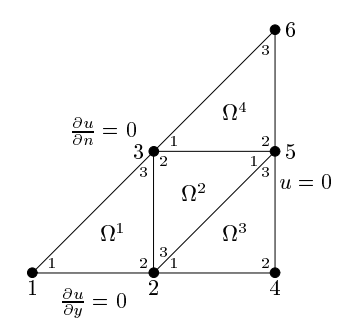

## Solution

This problem corresponds to the 2D BVP on the square $R=[0,1]\times [0,1]$ found in the document: [T2-MN-FEM2D-applications.pdf](https://numfactory.upc.edu/numfactory/subjects/FEM/FEM/theory/T2-MN-FEM2D-applications.pdf). In the current solution, we implement the 2D PDE model and take advantatge of the problem's symmetry.

#### Coeficients. 

The Poisson equation of this BVP fits the 2D PDE model,


$$-\frac{\partial}{\partial x}\left(a_{11}(x,y)\frac{\partial u}{\partial x} + a_{12}(x,y)\frac{\partial u}{\partial y}\right) - \frac{\partial}{\partial y}\left(a_{21}(x,y)\frac{\partial u}{\partial x} + a_{22}(x,y)\frac{\partial u}{\partial y}\right) + a_{00}(x,y) u = f(x,y),$$


with $a_{11} = a_{22} \equiv 1$, $a_{12} = a_{21} = a_{00}\equiv 0$, $f\equiv 1$. 

clearvars
close all

a11 = 1.0;
a12 = 0.0;
a21 = a12;
a22 = a11;
a00 = 0.0;
f = 1.0;


#### Geometry: position of the nodes and elements

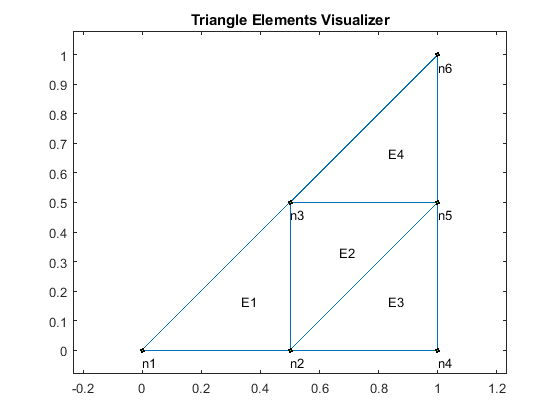


nodes=[
    0.0, 0.0;
    0.5, 0.0;
    0.5, 0.5;
    1.0, 0.0;
    1.0, 0.5;
    1.0, 1.0
    ];

elem = [
    1, 2, 3;
    5, 3, 2;
    2, 4, 5;
    3, 5, 6
    ];

numNodes = size(nodes,1);
numElem = size(elem,1);

numbering=1;

plotElements(nodes,elem,numbering);

#### Computation of the global stiffness matrix and global load vector

K=zeros(numNodes);
F=zeros(numNodes,1);
coeff=[a11,a12,a21,a22,a00,f];

for e = 1:numElem
    [Ke,Fe] = linearTriangElementShort(coeff,nodes,elem,e);
    rows=[elem(e,1),elem(e,2),elem(e,3)];
    cols=rows;
    K(rows,cols) = K(rows,cols) + Ke;
    if coeff(6) ~= 0
        F(rows,1) = F(rows,1) + Fe;
    end
end

#### Boundary Conditions (B.C.)

%B.C.
fixedNodes=[4,5,6];
freeNodes=setdiff(1:numNodes,fixedNodes);

%Essential B.C.
u = zeros(numNodes,1);
u(fixedNodes) = 0.0;

%Natural B.C.:
Q=zeros(numNodes,1);
Q(freeNodes) = 0.0; %all of them are zero

%Reduced system
Im = F(freeNodes) + Q(freeNodes) - K(freeNodes,fixedNodes)*u(fixedNodes);
Km = K(freeNodes,freeNodes);

#### Compute the solution

Solve the reduced system

%Solve the reduced system
um = Km\Im;
u(freeNodes) = um;

format short e
u

u =    3.1250e-01
   2.2917e-01
   1.7708e-01
            0
            0
            0


#### Post-process

Compute the secondary variables, write a table with the results and contour plot

%PostProcess: secondary varibles, table and contour plot
%Secondary variables
Q = K*u-F

Q =   -6.9389e-18
   1.1102e-16
            0
  -1.5625e-01
  -3.0208e-01
  -4.1667e-02


%Table: create an structure
Table.NodeNum=(1:numNodes)';
Table.X=nodes(:,1);
Table.Y=nodes(:,2);
Table.U=u;
Table.Q=Q;
struct2table(Table)

ans = 6×5 table
     NodeNum          X             Y             U              Q     
    __________    __________    __________    __________    ___________

    1.0000e+00    0.0000e+00    0.0000e+00    3.1250e-01    -6.9389e-18
    2.0000e+00    5.0000e-01    0.0000e+00    2.2917e-01     1.1102e-16
    3.0000e+00    5.0000e-01    5.0000e-01    1.7708e-01     0.0000e+00
    4.0000e+00    1.0000e+00    0.0000e+00    0.0000e+00    -1.5625e-01
    5.0000e+00    1.0000e+00    5.0000e-01    0.0000e+00    -3.0208e-01
    6.0000e+00    1.0000e+00    1.0000e+00    0.0000e+00    -4.1667e-02


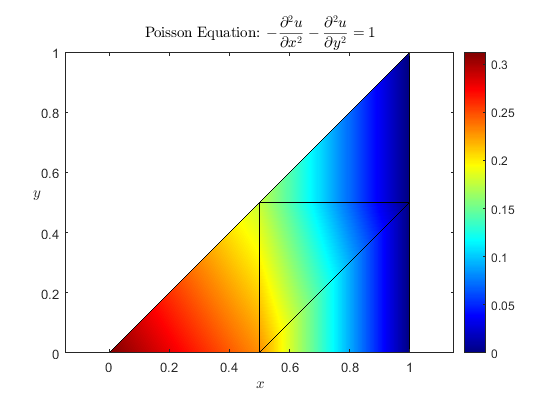


title = ['Poisson Equation: ', ...
         '$$-\frac{\partial^{2} u}{\partial x^{2}}-',...];
         '\frac{\partial^{2} u}{\partial y^{2}} = 1$$'];
xLabel = '$$x$$';
yLabel = '$$y$$';
colorScale = 'jet'; 
plotContourSolutionLT(nodes,elem,u,title,xLabel,yLabel,colorScale)